# `Creación del primer modelo de la red neuronal CNN 2    `

`Este modelo consiste en una red convolución que se toma de referencia de la propiuesta en el link de MATLAB, esta red no posee capa de maxpooling, únicamente las capas convolucionales con la función de activación ReLU. El tamaño del filtro es de 3x3, lo cual permite un menor número de parámetros entrenables comparado con el primer modelo desarrollado y redes más profundas (más capas pero menos densidad), así mismo, se emplea un padding de same y capas de maxpooling, lo cual ayuda a mantener el tamaño de la entrada y extraer las características más importantes de la cuadrícula de recursos.`

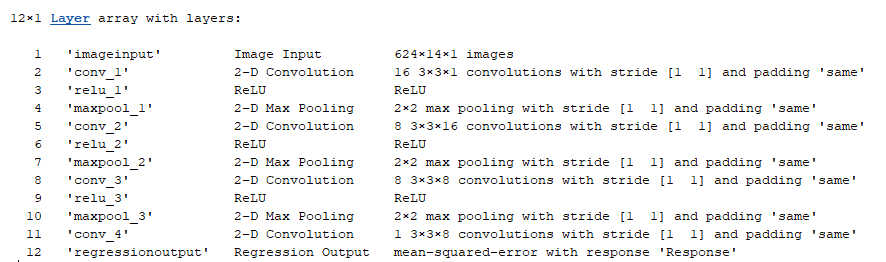

clc; clear all;

enable_Train = true;
data = load("X_train.mat");
label = load("Y_train.mat");

%Se importan los datos y las variables asociadas con los datos para el
%entrenamiento
data = data.x_train;
label = label.y_train;

size(label)

ans =          624          14           2        1000


[subport, simbolos, valor] = size(label)

subport = 624

simbolos = 14

valor = 2000

ratio = 0.75; %Porcentaje para la separación de los datos

[trainId,~,testId] = dividerand(1000,ratio,0.0,1-ratio);

x_train = data(:,:,:,trainId);
y_train = label(:,:,:,trainId);

x_val = data(:,:,:,testId);
y_val = label(:,:,:,testId);

x_train = cat(4, x_train(:,:,1,:), x_train(:,:,2,:));
y_train = cat(4, y_train(:,:,1,:), y_train(:,:,2,:));

x_test = cat(4, x_val(:,:,1,:), x_val(:,:,2,:));
y_test = cat(4, y_val(:,:,1,:), y_val(:,:,2,:));

rng(42);

if enable_Train
    batch = 32; % Es el número de ejemplos que se introducen en la red.
    
    %Esta variable se usa para verificar 5 veces en cada época.
    valFrequency = round(size(x_train,4)/batch/5); 


    %Aquí se puede definir las capas que van a componer la RNA

    capas = [
        imageInputLayer([subport simbolos 1],'Normalization','none')
        convolution2dLayer(3,16,'Padding','same')
        reluLayer
        maxPooling2dLayer(2,"Padding","same")
        convolution2dLayer(3,8,'Padding','same')
        reluLayer
        maxPooling2dLayer(2,"Padding","same")
        convolution2dLayer(3,8,'Padding','same')
        reluLayer
        maxPooling2dLayer(2,"Padding","same")
        convolution2dLayer(3,1,'Padding','same')
        regressionLayer
    ]


    hiper_param = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',5, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batch, ...
        'ValidationData',{x_test, y_test}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);


    [estimacionRNA, infoRNA] = trainNetwork(x_train, ...
        y_train,capas,hiper_param);

    save('Modelo2.mat', "estimacionRNA");

else
    load("Modelo2.mat");
end

capas =   12×1 Layer array with layers:

     1   ''   Image Input         624×14×1 images
     2   ''   2-D Convolution     16 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                ReLU
     4   ''   2-D Max Pooling     2×2 max pooling with stride [1  1] and padding 'same'
     5   ''   2-D Convolution     8 3×3 convolutions with stride [1  1] and padding 'same'
     6   ''   ReLU                ReLU
     7   ''   2-D Max Pooling     2×2 max pooling with stride [1  1] and padding 'same'
     8   ''   2-D Convolution     8 3×3 convolutions with stride [1  1] and padding 'same'
     9   ''   ReLU                ReLU
    10   ''   2-D Max Pooling     2×2 max pooling with stride [1  1] and padding 'same'
    11   ''   2-D Convolution     1 3×3 convolutions with stride [1  1] and padding 'same'
    12   ''   Regression Output   mean-squared-error